# ELEX7620 Lab 3

Name:  Ryan Wong, A00958475, and set:T

Objective:  to simulate and measure a Tow-Thomas biquadratic filter frequency response.

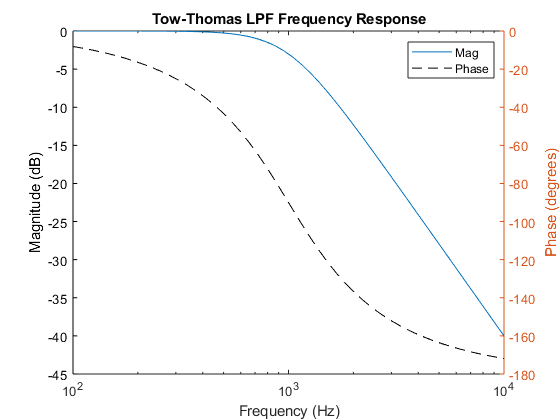

fc= 1e3;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = sqrt(2)^(-1);
k = 1;

%modify the code below to create the transfer function
%store transfer function in variable name H
b = k * wc^2;
a = [1 2*zeta*wc wc^2];
H = tf(b,a);

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Tow-Thomas LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for LPTow-Thomas Filter 

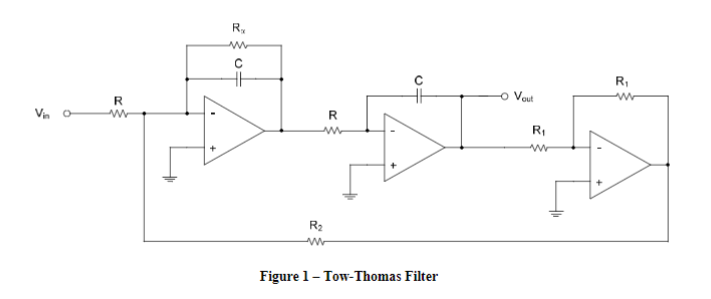

%Show your work for the steps below by inserting some documentation above or below this code block


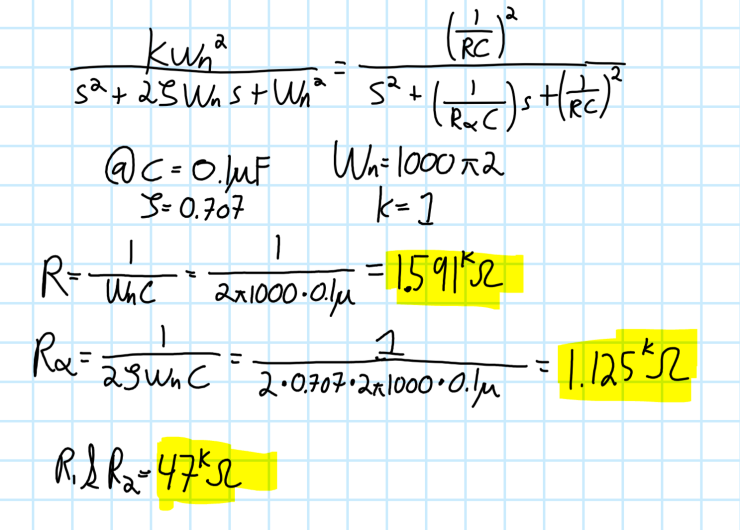

## LTSPICE Schematic for a LP Tow-Thomas Filter

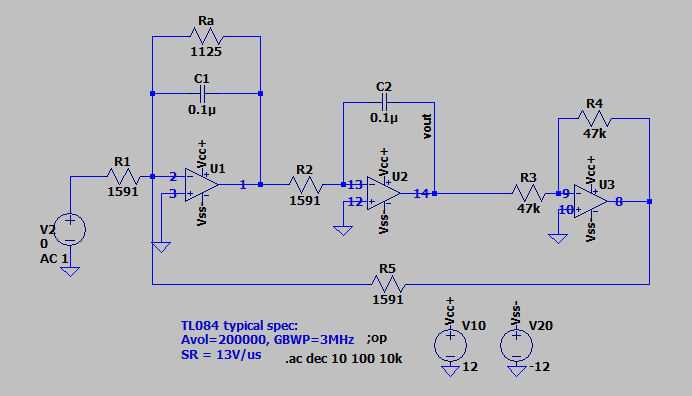

## LTSPICE Simulation Results for a LP Tow-Thomas Filter

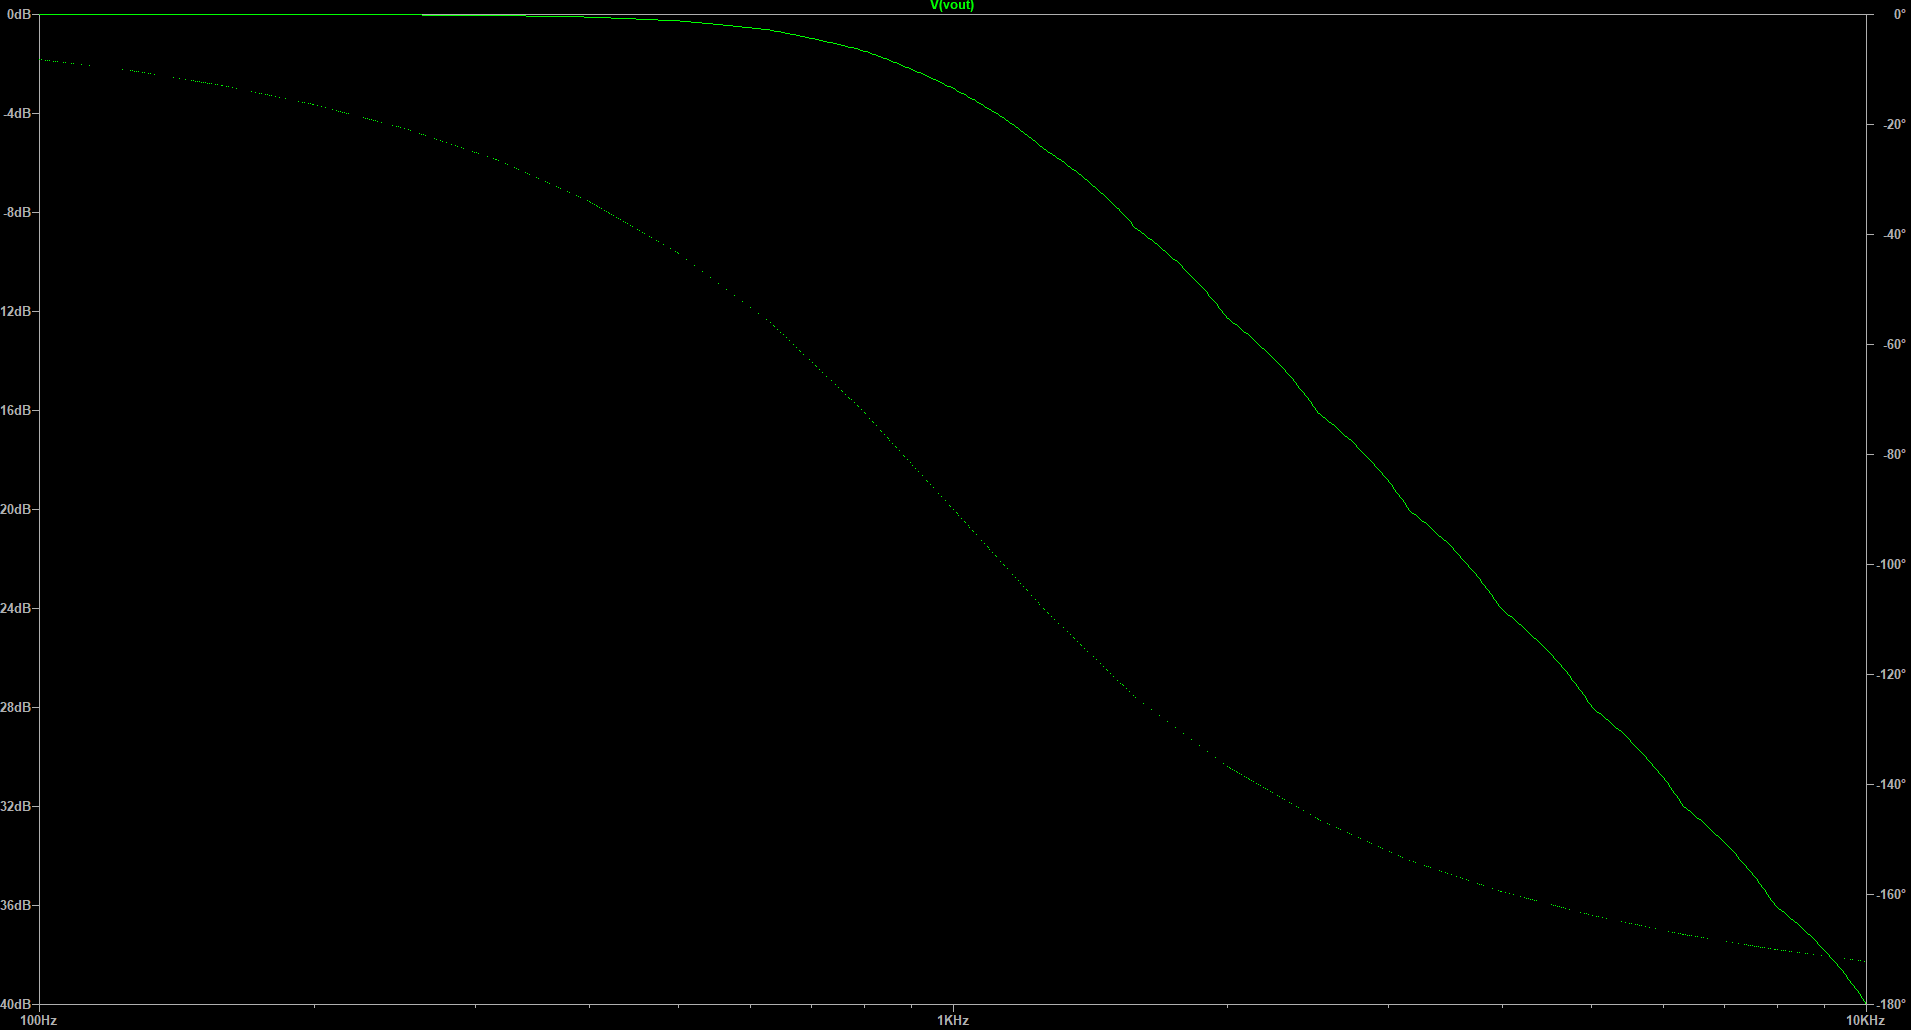

## Measurements for a LP Tow-Thoams Filter

Record your measured data here and compare it against the theoretical results

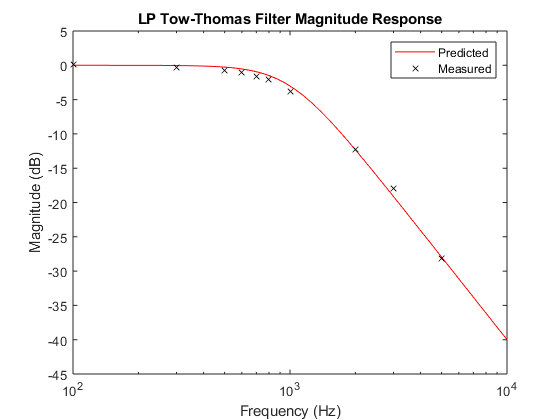

%Measured data; each triplet [f,vout,delay] is
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[100, 2.08, 268e-6]
            [300, 1.99, 252e-6]
            [500, 1.90, 240e-6]
            [600, 1.83, 260e-6]
            [700, 1.72, 264e-6]
            [800, 1.61, 256e-6]
            [1000, 1.33, 256e-6]
            [2000, 0.504, 198e-6]
            [3000, 0.260, 146e-6]
            [5000, 0.081, 89e-6]
    ];
% The measurements are closer to the LTSpice prediction 
% as it takes the GBWP into consideration

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 2.06;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LP Tow-Thomas Filter Magnitude Response')
legend('Predicted', 'Measured')

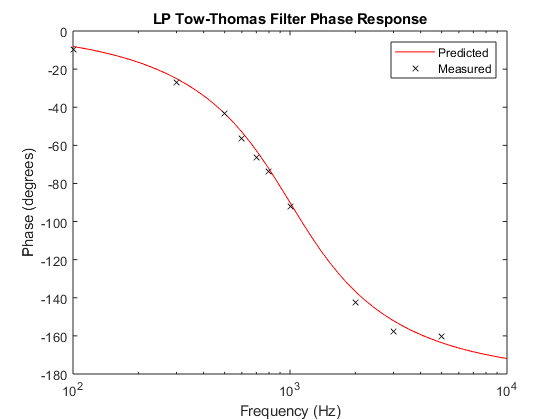


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('LP Tow-Thomas Filter Phase Response')
legend('Predicted', 'Measured')

## Tow-Thomas Bandpass Simulation

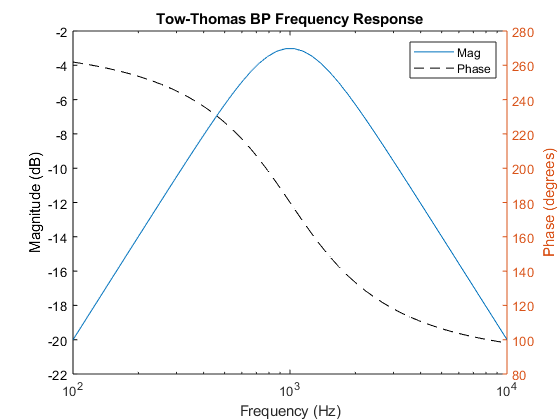

fc= 1e3;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = sqrt(2)^(-1);
k = 1;
R = 1591;
Ra = 1125;
C = 0.1e-6;

%modify the code below to create the transfer function
%store transfer function in variable name H
b = [-(R*C)^(-1) 0];
a = [1 1/(Ra*C) (R*C)^(-2)];
H = tf(b,a);

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Tow-Thomas BP Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Tow-Thomas Bandpass Gain at 1kHz

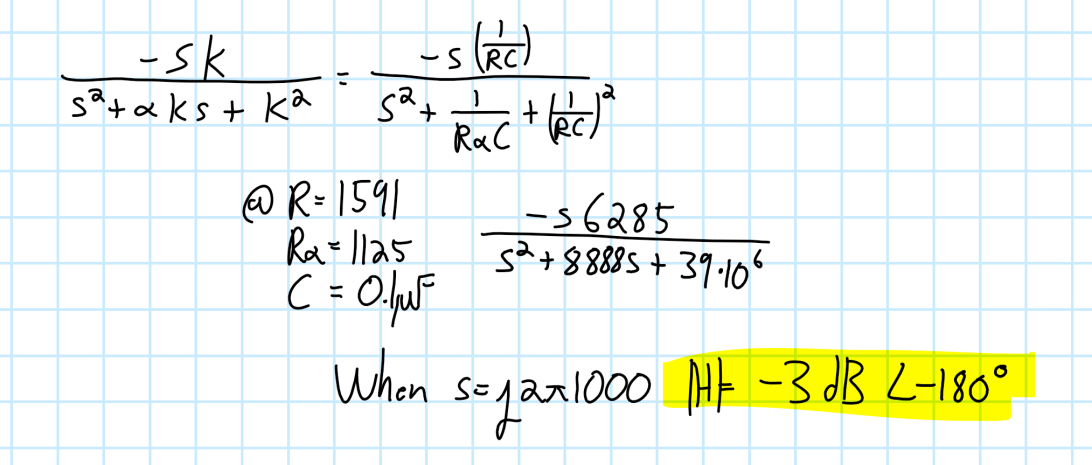

## LTSPICE Schematic for a BP Tow-Thomas Filter

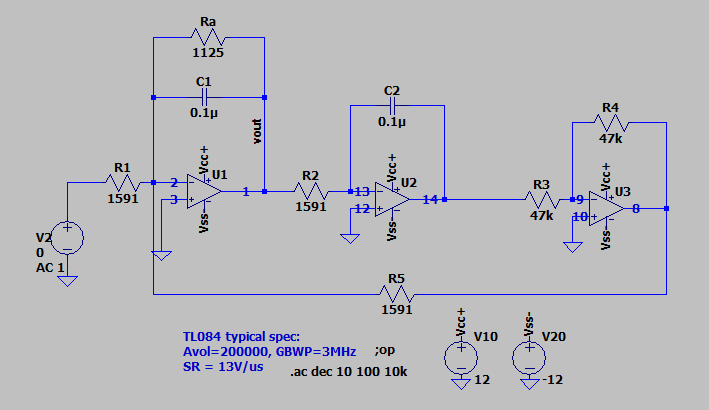

## LTSPICE Simulation Results for a BP Tow-Thomas Filter

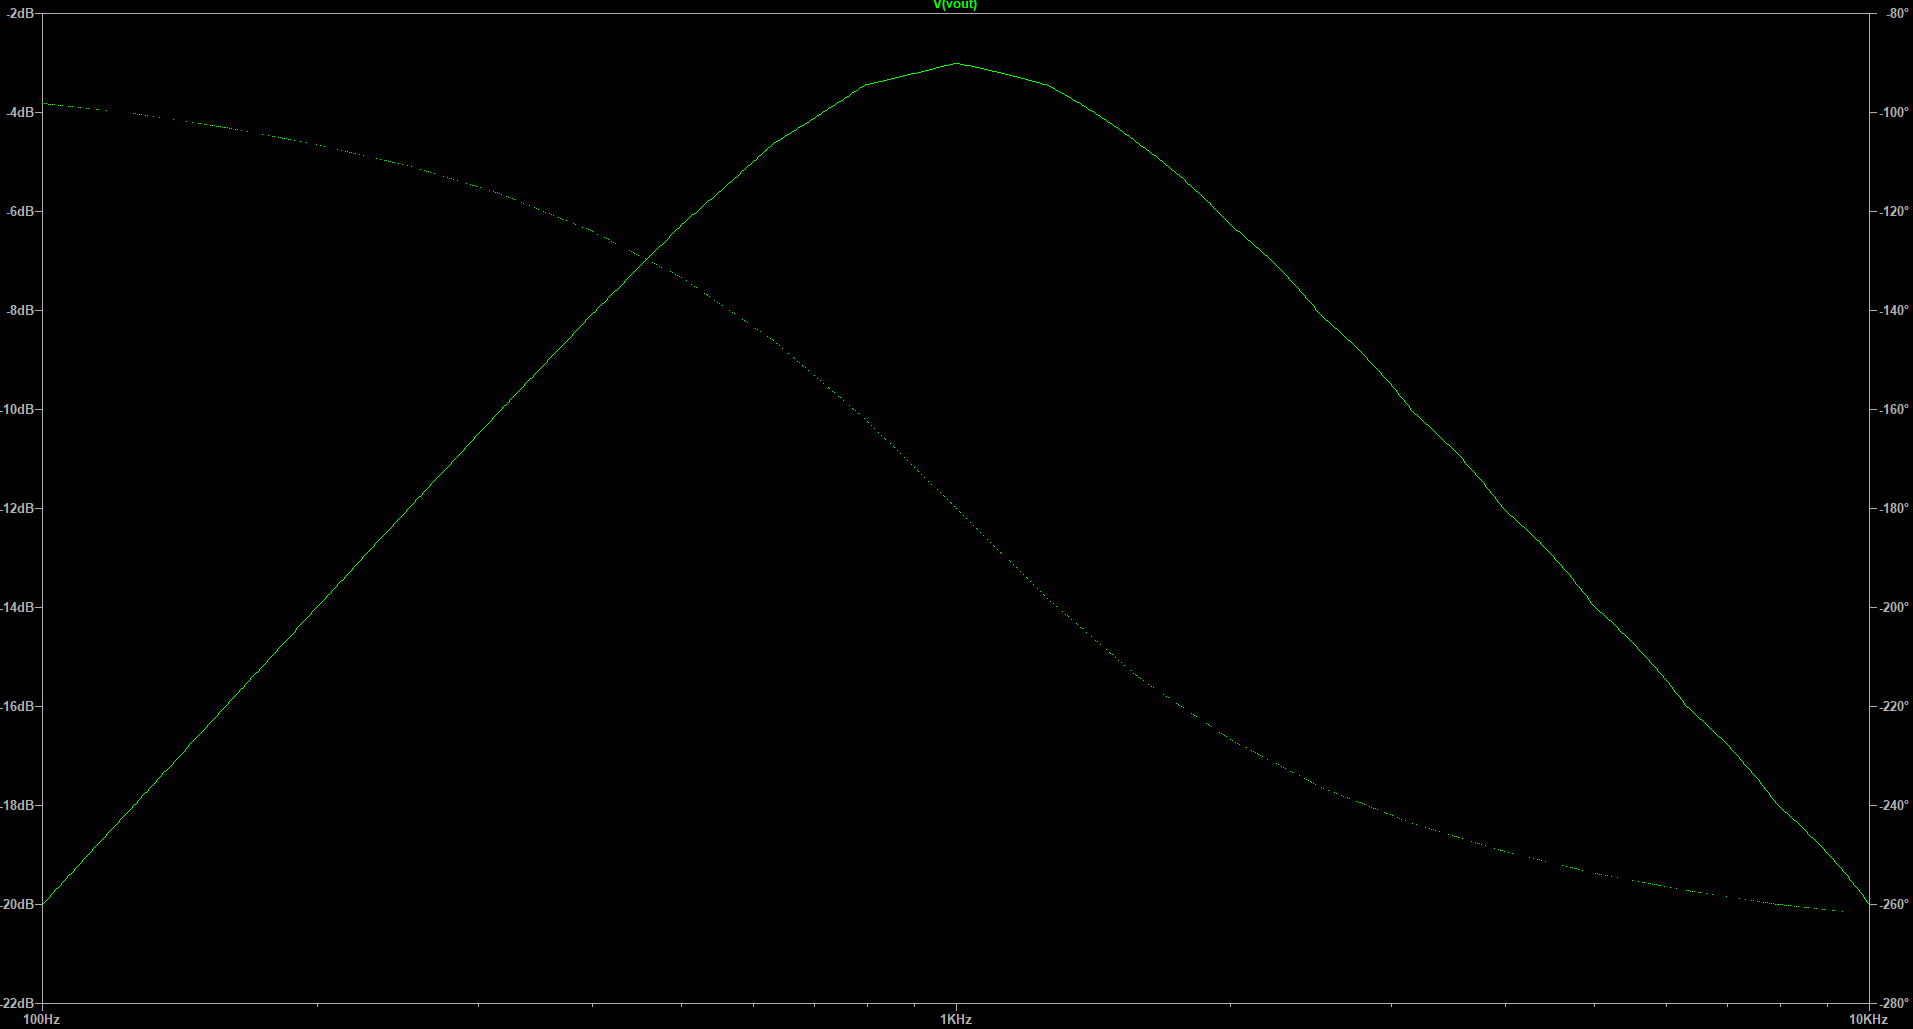

## Measurements for a BP Tow-Thoams Filter

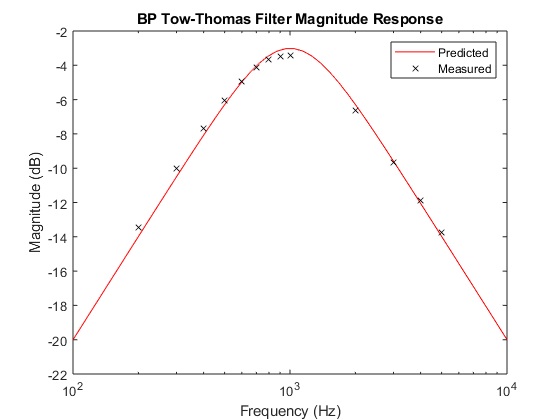

%Measured data; each triplet [f,vout,delay] is
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[200, 0.426]
            [300, 0.632]
            [400, 0.824]
            [500, 00.994]
            [600, 1.13]
            [700, 1.24]
            [800, 1.31]
            [900, 1.34]
            [1000, 1.35]
            [2000, 0.932]
            [3000, 0.656]
            [4000, 0.508]
            [5000, 0.410]

    ];
% The measurements are closer to the LTSpice prediction 
% as it takes the GBWP into consideration

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 2;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('BP Tow-Thomas Filter Magnitude Response')
legend('Predicted', 'Measured')

## Bessel vs Butterworth Lowpass Simulation

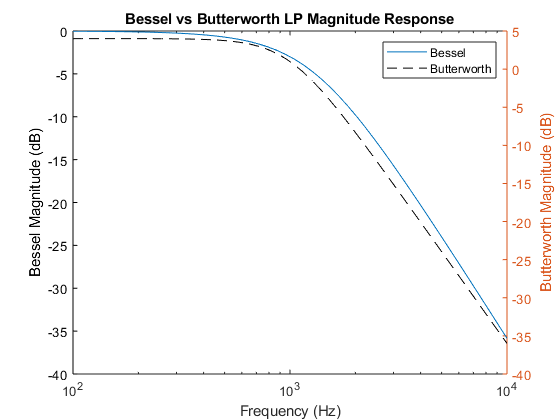

fc= 1e3;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = sqrt(2)^(-1);
k = -sqrt(2) + 3;

%modify the code below to create the transfer function
%store transfer function in variable name H

%Butterworth Transfer function
b = k * wc^2;
a = [1 2*zeta*wc wc^2];
H = tf(b,a);

%Bessel Transfer function
[b1, a1] = besself(2, wc*1.2754, 'low');
H1 = tf(b1,a1);


%plot the frequency response
freq = logspace(2,4,50);
[mag1, phase1] = bode(H1,2*pi*freq);
[mag, phase] = bode(H,2*pi*freq);

%magnitude graph
mag_dB1 = 20*log10(abs(mag1(:,:)));
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB1)
xlabel('Frequency (Hz)')
ylabel('Bessel Magnitude (dB)')
title('Bessel vs Butterworth LP Magnitude Response')
hold on
yyaxis right
semilogx(freq,mag_dB, 'k--')
ylabel('Butterworth Magnitude (dB)')
legend('Bessel','Butterworth')
hold off

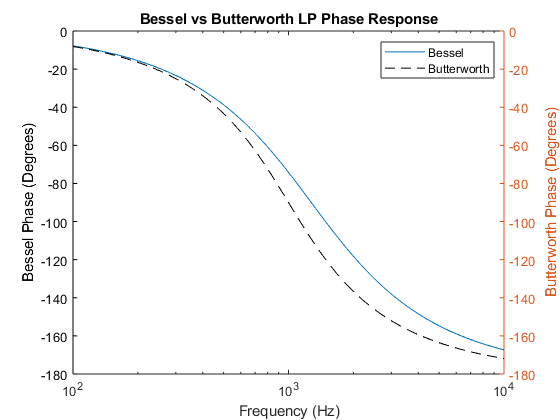


%phase graph
figure(2)
clf
semilogx(freq,phase1(:,:))
xlabel('Frequency (Hz)')
ylabel('Bessel Phase (Degrees)')
title('Bessel vs Butterworth LP Phase Response')

hold on
yyaxis right
semilogx(freq,phase(:,:), 'k--')
ylabel('Butterworth Phase (Degrees)')
legend('Bessel','Butterworth')
hold off

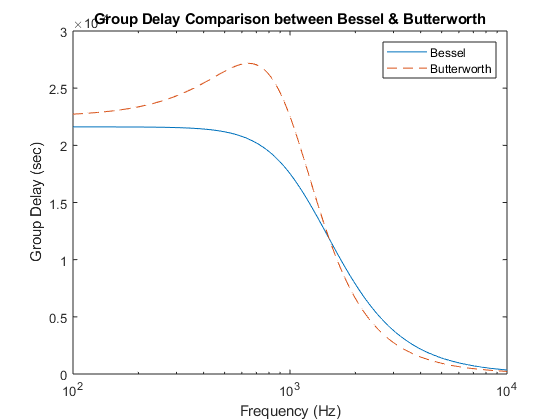


%groupe delay graph
figure(3)
clf
%bessel
freq_TG =[1:1:10^5];
[~, phase_TG] = bode(H1,2*pi*freq_TG);
y = phase_TG(:,:) .* 0.0174533 ;
x = 2*pi*freq_TG;
dydx = -diff([eps; y(:)])./diff([eps; x(:)]);
semilogx(x./(2*pi), dydx')
hold on
% butterworth
[mag1, phase_TG] = bode(H,2*pi*freq_TG);
y = phase_TG(:,:) .* 0.0174533;
x = 2*pi*freq_TG;
dydx = -diff([eps; y(:)])./diff([eps; x(:)]);
semilogx(x./(2*pi), dydx', 'LineStyle','--')
xlim([10^2 10^4])
xlabel('Frequency (Hz)')
ylabel('Group Delay (sec)')
title('Group Delay Comparison between Bessel & Butterworth')
legend('Bessel','Butterworth')
hold on

## Calculate Component Values for Bessel LPF in Tow-Thomas Form 

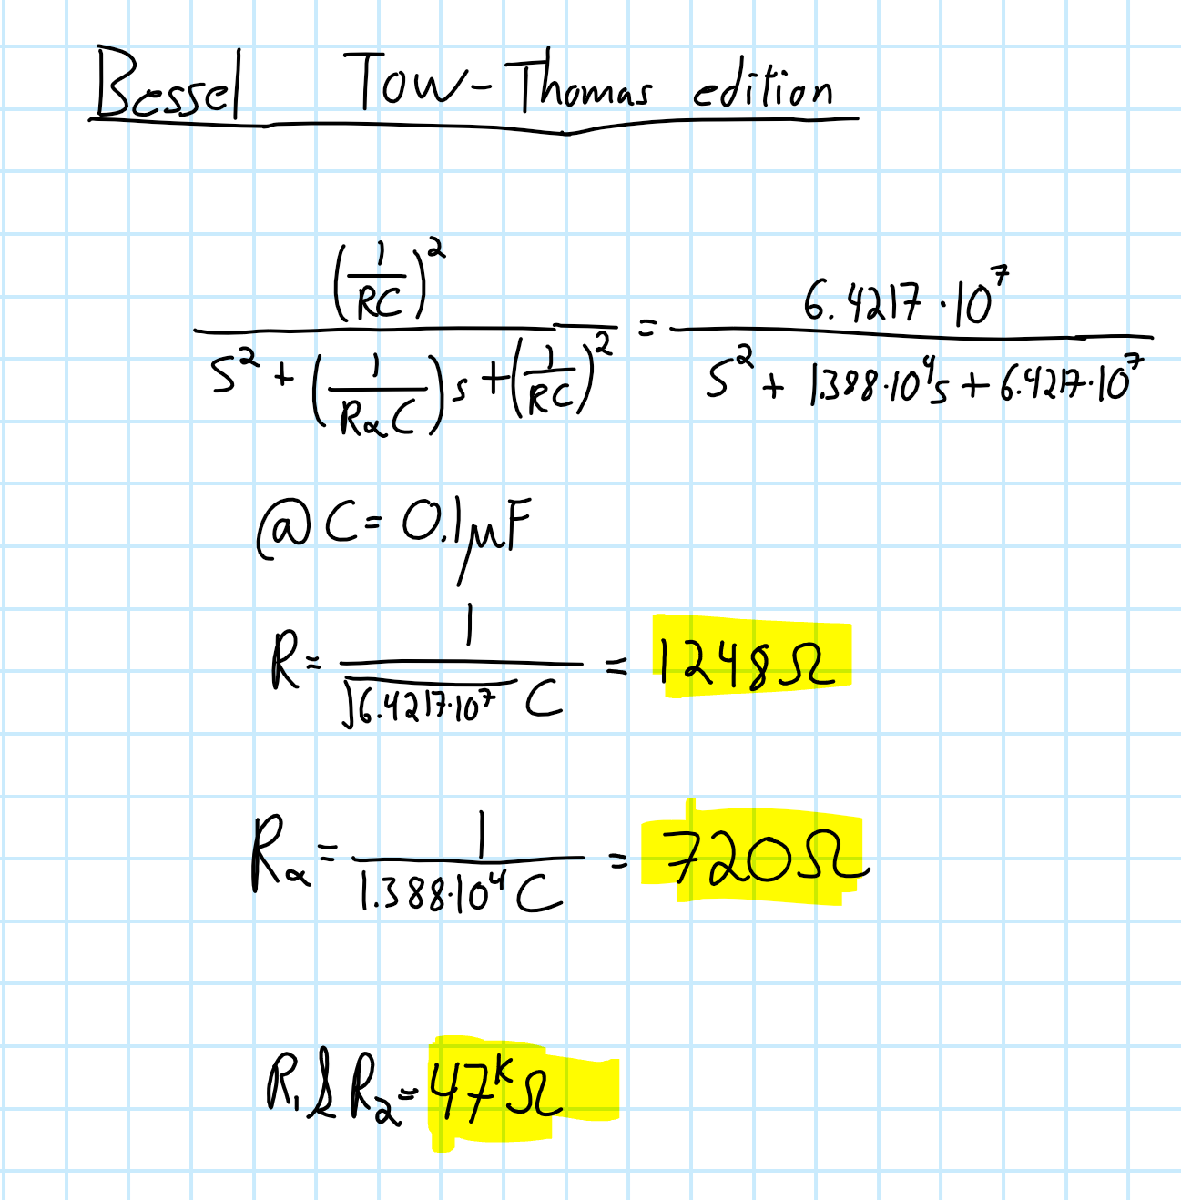

## LTSPICE Schematic for a Bessel Tow-Thomas Low Pass Filter

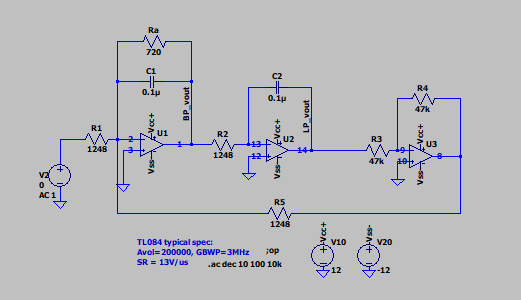

## LTSPICE Simulation Results for a Bessel Tow-Thomas Low Pass Filter

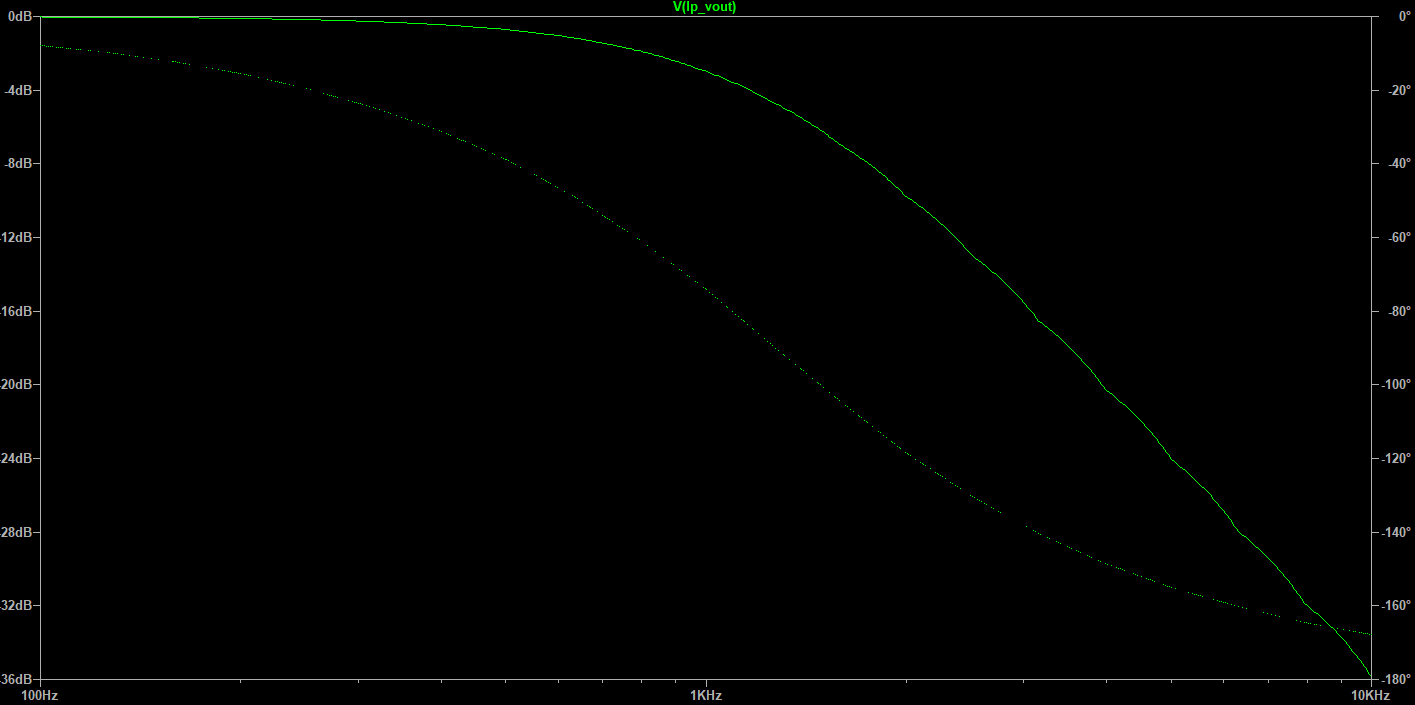

## Measurements for a Bessel Tow-Thoams Filter Low Pass Filter

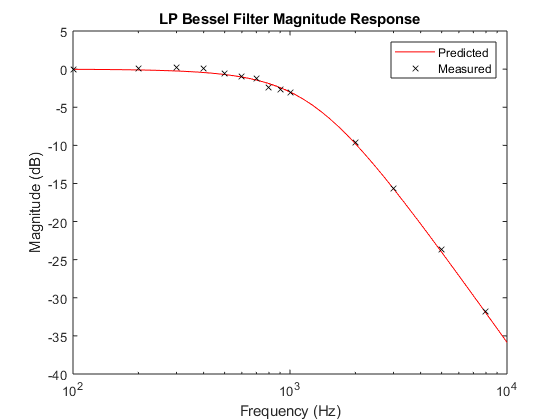

%Measured data; each triplet [f,vout,delay] is
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[100, 2.02, 204e-6]
            [200, 2.05, 220e-6]
            [300, 2.06, 220e-6]
            [400, 2.04, 216e-6]
            [500, 1.9, 216e-6]
            [600, 1.8, 232e-6]
            [700, 1.76,220e-6]
            [800, 1.53, 216e-6]
            [900, 1.48, 208e-6]
            [1000, 1.41, 212e-6]
            [2000, 0.668, 166e-6]
            [3000, 0.332, 130e-6]
            [5000, 0.132, 88e-6]
            [8000, 0.052, 59e-6]
    


    ];
% The measurements are closer to the LTSpice prediction 
% as it takes the GBWP into consideration

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 2.02;




meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB1,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LP Bessel Filter Magnitude Response')
legend('Predicted', 'Measured')

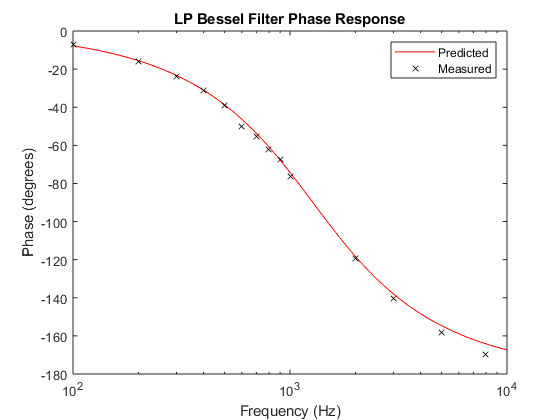


figure(3)
clf
semilogx(freq,phase1(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('LP Bessel Filter Phase Response')
legend('Predicted', 'Measured')

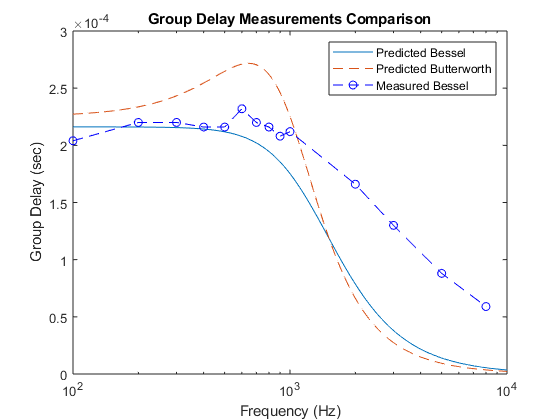


figure(4)
clf
freq_TG =[1:1:10^5];
[~, phase_TG] = bode(H1,2*pi*freq_TG);
y = phase_TG(:,:) .* 0.0174533 ;
x = 2*pi*freq_TG;
dydx = -diff([eps; y(:)])./diff([eps; x(:)]);
semilogx(x./(2*pi), dydx')
hold on
% butterworth
[mag1, phase_TG] = bode(H,2*pi*freq_TG);
y = phase_TG(:,:) .* 0.0174533;
x = 2*pi*freq_TG;
dydx = -diff([eps; y(:)])./diff([eps; x(:)]);
semilogx(x./(2*pi), dydx', 'LineStyle','--')
xlim([10^2 10^4])
xlabel('Frequency (Hz)')
ylabel('Group Delay (sec)')
title('Group Delay Measurements Comparison')
legend('Bessel','Butterworth')
hold on
 
y = meas_delay;
x = meas_freq;

semilogx(x, y , 'b--o')
legend('Predicted Bessel', 'Predicted Butterworth', 'Measured Bessel')
hold on